 clear ur;
 ur = urRTDEClient('192.168.1.10','CobotName','universalUR5e')

% % Cargamos una pose de prueba
 testPose = rad2deg(readJointConfiguration(ur)');
 
% % Cargamos una foto de prueba a su vez
 [imgdata,img] = fotosw()

imgdata = 480×640×3 uint8 array
imgdata(:,:,1) =

   197   183   167   171   169   179   208   210   197   175   181   176   169   199   184   197   206   195   178   179   190   213   229   213   203   214   204   217   204   226   199   218   228   222   220   210   212   225   227   231   218   230   223   229   239   238   241   231   229   226   198   228   225   231   215   226   237   245   237   240   233   226   239   241   232   230   213   241   230   239   244   251   247   250   255   246   254   243   251   247   251   250   247   247   245   244   238   239   255   254   252   248   248   254   255   253   227   239   246   250   254   250   252   251   253   251   251   251   254   254   250   255   255   254   255   255   255   255   253   255   255   255   252   255   254   254   254   251   252   253   255   255   250   255   254   253   255   253   254   255   255   255   255   255   255   255   255   254   254   254   255   254   255   250   254   252   252   251  

img = "actualphoto.jpg"

 testImage = imgdata; 

%Quitamos la distorcion de la foto con los parametros de la camara
 undistortedTestImage = undistortImage(testImage,ld.cameraParams);

%Calculamos la transoformada de la base al efector final de la pose anterior
testPoseRad = deg2rad(testPose);
endEffectorToBaseTformTest = getTransform(robotModel,testPoseRad,"robotiq_gripper");

% Especificamos la familia a la que pertenece el AprilTag.
tagFamily = "tag36h11"; %<<<<<--------------------CAMBIAR ESTO
tagSize = .049; % AprilTag tamaño en metros

% Detectamos el AprilTag en la imagen
[~,~,aprilTagToCameraTform] = readAprilTag(undistortedTestImage,"tag36h11",intrinsics,tagSize);

%Encontramos la transformada de la base del robot a la camara
cameraToBaseTestTform = rigidtform3d(endEffectorToBaseTformTest * cameraToEndEffectorTform.A);

%Encontramos la transformada de la base del robot al AprilTag
tagToBaseTestTform = cameraToBaseTestTform.A * aprilTagToCameraTform.A;
%Guardamos la posicion del apriltag en el espacio (cartesiano)
cubePosition = tagToBaseTestTform(1:3,4)

cubePosition =     0.2352
   -0.7181
   -0.0447


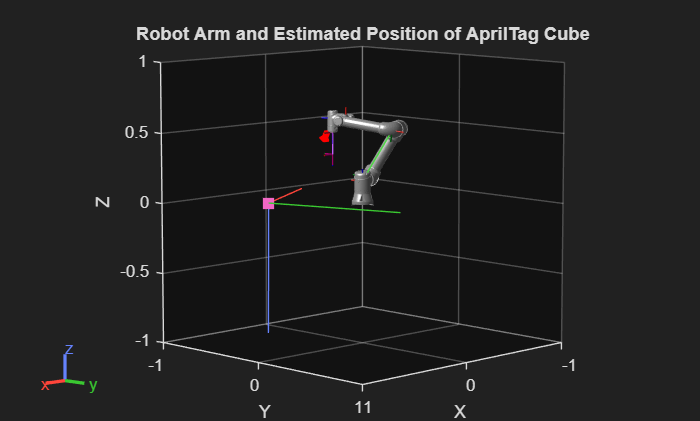

% Mostramos el modelo del robot
show(robotModel,testPoseRad);
hold on
rotate3d("on")
%Mostramos las posiciones estimadas y orientaciones de la camara y el cubo
plotCamera(AbsolutePose = cameraToBaseTestTform, Opacity=0, size=0.02)
scatter3(cubePosition(1), cubePosition(2), cubePosition(3), 75, 'square', 'filled')
cubeRotationQuaternion = rotm2quat(tagToBaseTestTform(1:3,1:3));
plotTransforms(cubePosition', cubeRotationQuaternion)
title("Robot Arm and Estimated Position of AprilTag Cube")
xlim([-1,1])
ylim([-1, 1])
zlim([-1,1])

%Vamos al objeto y nos regresamos
jointAngles = readJointConfiguration(ur) %Lee los angulos del brazo

jointAngles =     2.0312   -1.0290   -1.9699   -1.7135    1.5708   -2.6820


coci = car2pol(cubePosition(1),cubePosition(2),cubePosition(3))

coci =     0.7557   -1.2543   -0.0447


jointAngles = MoverRobot(coci,-1.57,pi,jointAngles,ur);
pause(5)
jointAngles = readJointConfiguration(ur) %Lee los angulos del brazo

jointAngles =     2.0646   -2.4014   -1.3096   -1.0014    1.5708   -2.9651


coci = car2pol(0,-0.3,0.3)

coci =     0.3000   -1.5708    0.3000


jointAngles = MoverRobot(coci,-1.57,pi,jointAngles,ur);